# Tutorial: Two-Tank System

In this tutorial you will learn how to

- Set up and initialize an MPC problem in CHRONOS

- A neat trick to build LPV models from a nonlinear system not affine on the state variables

- Define and enforce standard box constraints in CHRONOS

- Add custom inequality constraints and custom cost terms

- Incorporate terminal ingredients for stability

- Perform nonlinear MPC in closed loop by updating the LPV model each step making use of CHRONOS update API

- Run a full MPC simulation in closed-loop and plot the results

## MPC Initialization

#### Two-Tank System introduction

The two tanks system is a classical example used in control lectures. It consists of two inter-connected cylindrical tanks, where the first tank receives a steady flow of water, which can be regulated, and the second tank has a downstream discharge of water at its base. The nonlinear equations that describe the water height dynamics on each tank are the following:


$$$$ \dot h_1 = u/A_b-\sqrt{2gh_1}/A_b $$
$$ \dot h_2 = \sqrt{2gh_1}/A_b-\sqrt{2gh_2}/A_b $$$$


where $$g$$ is the gravity acceleration and $$A_b$$ is the tanks area. The states $h_1$ and $h_2$ are the tanks water height and $u$ is the controlled mass flow of water into tank 1.

Lets assume that both tanks start with the same amount of water and that our control system for the water heights works at 100Hz sampling frequency. We then define the model parameters and initial condition for the states as:

% Tank area and gravity value
Ab = 1;
g = 9.81;

% Initial condition
h1 = 0.45;
h2 = 0.45;

% Sampling time
Ts = 0.01;

#### Creating the MPC object

In CHRONOS, we initialize the MPC structure with the init_mpc() function. We pass to this function the lenght of the prediction horizon $N$. Optionally, we  can also choose to use a control horizon smaller than the prediction horizon by passing it as a second argument. 

For this tutorial we choose a prediction horizon of lenght 10 samples with a control horizon of length 5 samples.

N = 10;         % Prediction Horizon
N_h_ctr = 5;    % Control Horizon

% Create mpc struct
mpc = init_mpc(N,N_h_ctr);

#### Defining the system model

CHRONOS is a tailored convex solver for **Linear Parameter-Varying** (LPV) systems. Rather than tackling nonconvex system equations head-on, by using the LPV paradigm CHRONOS keeps every control update strictly convex, this LPV philosophy guarantees real-time feasibility and robustness for complex time-varying systems. There are many ways to obtain LPV models from your nonlinear dynamical system, however, if you don’t already have an LPV description of your system, one can always construct it on the fly via local Taylor-series linearizations around the current operating point. 

For the two-tank system, we are going to obtain an LPV system with some simple manipulations. Notice that the dynamics are affine on the input $u$ but not on the states $[h_1, h_2]$. In this case  we can multiply and divide each square root term by the respective state variable $h_i$ involved 


$${\sqrt{2gh_i}\cdot\frac{h_i}{h_i}$$


such that now we can extract the following LPV model:


$$$$ \left [\begin{array}{c} \dot h_1\\\ \dot h_2 \end{array} \right ] =
\left [\begin{array}{cc}  -\sqrt{2gh_1}/(h_1A_b) & 0\\\ \sqrt{2gh_1}/(h_1A_b & -\sqrt{2gh_2}/(h_2A_b)\end{array} \right ]
\left [\begin{array}{c} h_1\\\ h_2 \end{array} \right ] + 
\left [\begin{array}{c} 1/A_b\\\ 0 \end{array} \right ]u$$$$


Note that if we expand the state-space LPV model, we recover the exact nonlinear dynamics of the two-tank system. This highlights a key advantage of the LPV representation: it captures the full nonlinear behavior of the system while casting it in a form compatible with convex optimization. 

During initialization, we need to define the LPV model at some operation point, so that CHRONOS is aware of the system dimentions. We also need to define the measurement model for the signal we want the MPC to track. For this example, we want to control the water level of the second tank:


$$y = h_2 = \left [\begin{array}{cc} 0 &  1\end{array} \right ] 
\left [\begin{array}{c} h_1\\\  h_2 \end{array} \right ] $$


Finally, note that the system description have been done so far using continous-time models, however, for MPC we require discrete-time models. We perform here the discretization using the forward Euler method, which is perhaps the most computationally effective discretization method. We then define the system dynamics for the two-tank system as follows:

% Get the LPV model frozen at initial state vector

A = [-sqrt(2*g)*sqrt(h1)/(Ab*h1) 0;
     sqrt(2*g)*sqrt(h1)/(Ab*h1) -sqrt(2*g)*sqrt(h2)/(Ab*h2)];

B = [1/Ab; 0];

% System discretized with forward Euler discretization:
% x+ = (I+Ts*A)*x+Ts*B*u+Ts*Bd*d

Ad = eye(2)+Ts*A;
Bd = Ts*B;

% Tracking objective is the water height on the second tank

C = [0 1];

% Initialize system dynamics in CRHONOS
mpc = init_mpc_system(mpc,Ad,Bd,0,C,0,0);

#### Defining the constraints

CHRONOS provide a simple API to define standard MPC box constraints on:

- all states $x$

- only on the terminal state of the prediction horizon $x_N$

- control action $u$

- control action variation between samples $\Delta u$

- on the output signal $y$

For this tutorial we are going to define the following constraints:


$$$$ h_1,h_2 \in [0.01,\ 1]$$
$$ u \in [0,\ 10]$$


which is performed using CHRONOS as follows:

% State constraints
x_min = 0.01*ones(mpc.nx,1);
x_max = 1*ones(mpc.nx,1);
mpc = init_mpc_state_cnstr(mpc,x_min,x_max);

% Control input constraints
u_min = 0*ones(mpc.nu,1);
u_max = 10*ones(mpc.nu,1);
mpc = init_mpc_u_cnstr(mpc,u_min,u_max);

#### **Using custom constraints**

CHRONOS also provides the user with the capability to define custom inequalites. For this functionality, the user most define the signal to be constrained using the State-Space system output model:


$$h = C_h\cdot x + D_h\cdot u + D_{dh} \cdot d_i$$


by defining the matrices $C_z$, $D_z$ and $D_{dz}$. The constraints are then defined by indicating the upper and lower limits on the user defined custom signal $h$.

For the two-tank system, we are going to force the control action $u$ to stay within a certain distance of an externally provided equilibrium point control action $u^\star$, e.g. we want to constraint $h = u-u^{\star}$. This custom signal is modelled with the following output model:


$$h=  [0,\ 0]\cdot x + 1\cdot u - 1 \cdot d_i$$


where we will use the measured disturbance input $d_i$ to enter in CHRONOS the equilibrium point control action $u^\star$ during MPC runtime.

% h = u-u_star
Ch = [0 0];
Dh = 1;
Ddh = -1;

% Constraint limits
h_min = -0.5;
h_max = 0.5;

mpc = init_mpc_lin_custom_cnstr(mpc,h_min,h_max,Ch,Dh,Ddh);

#### Terminal Ingredients

Terminal ingredients are key in MPC to provide stability gurantees and improve performance in problems where the user chooses small control horizons. The ingredients are:

- Terminal cost: $\min J_N =(x_{N_{ref}}-x_N)^T \cdot P \cdot (x_{N_{ref}}-x_N)$

- Terminal ellipsoidal set: $(x_{N_{ref}}-x_N)^T \cdot P \cdot (x_{N_{ref}}-x_N)-1\leq 0$ (not currently recommendable)

Notice that independently of the tracking signal $y$ set during the initialization of the system dynamics, the use of the terminal ingredients requires the user to pass a reference $x_{N_{ref}}$ for the full state vector of the terminal step on the prediction horizon. 

CHRONOS provides an api function to allow initialization of terminal ingredients using the dLQR method to compute internally the terminal cost $P$. We must provide the function with a penalty cost matrix for state tracking $Q_x$ and penalty cost matrix for the control input $R_u$. The CHRONOS API also let us choose if we want to use the terminal set constraint in addition to the termina cost, which we will disable for this example.

%% Terminal Ingredients

% Terminal ingredients are computed using the dLQR method
Qx = diag([30 30]);         % State Penalty
Ru = 1;                     % Control Penalty
ter_constraint = 0;         % Only terminal cost
x_ref_is_y = 0;             % The terminal reference cannnot be extracted 
                            % from the mpc tracking reference

% Initialize terminal ingredients using the dLQR method                           
[mpc] = init_mpc_ter_ingredients_dlqr(mpc,Qx,Ru,ter_constraint,x_ref_is_y);

#### Defining the cost function

CHRONOS provides intuitive API functions to initializes standard MPC cost functions terms:

- Penalty on tracking error: $\min J_e =\sum_{i=1}^{N-1}(r_i-y_i)^T \cdot Q_e \cdot (r_i-y_i)$

- Penalty on control action: $\min J_u =\sum_{i=0}^{N-1}u_i^T \cdot R_u\cdot u_i + r_u^T\cdot u_i$ 

- Penalty on control action variation between consecutive samples: $\min J_{\Delta u} =\sum_{i=0}^{N-1}\Delta u_i^T \cdot R_{\Delta u} \cdot \Delta u_i$

For this tutorial we will define a penalty on the tracking error: $e = r-h_2$

% Tracking penalty
Qe = diag(50*ones(mpc.ny,1));
mpc = init_mpc_Tracking_cost(mpc,Qe);

#### Using custom terms on the cost function

CHRONOS allows the user to define custom cost functions. This is done by defining a custom signal $z$ using the State-Space system output model:


$$z = C_z\cdot x + D_z\cdot u + D_{dz} \cdot d_z$$


The user then can complete the definition of the custom cost term by providing one or both of:

- a penalty matrix on quadratic cost $Q_z$

- a penalty vector on linear cost $q_z$ (only advisable if $z$ is strictly positive)

Combining all items, the custom cost function takes the following form:


$$\min J_z =\sum_{i=1}^{N-1}z_i^T \cdot Q_z\cdot z_i + q_z^T\cdot z_i$$


For the two-tank system we will define a quadratic penalty on the deviation of the control action with respect the specified equilibrium control action $u^\star$, e.g. $z = u-u^\star$.

% z = u-u_star
Cz = [0 0];
Dz = 1;
Ddz = -1;

Qz = 1;    % Quadratic penalty on performance vector: z'*Qz*z
qz = [];    % Linear penalty on performance vector: qz'*z 

% Init performance cost
mpc = init_mpc_Lin_Custom_cost(mpc,Cz,Dz,Ddz,Qz,qz);

#### Initializing the optimization vector and modifying solver hyperparameters

CHRONOS is an iterative solver, and requires an initial guess as starting point. The simplest way to compute an adequate value for the initial guess is making use of the init warmstart API function. This function runs CHRONOS feasibility solver to find an initial point for the MPC solver that takes into account the constraints defined on the MPC problem initialization and the system dynamics.

% use warm start init function to get optimization vector initial value
x_prev = [h1; h2];
u_prev = 3.7;
x0 = init_mpc_warm_start(mpc,x_prev,u_prev,[],[],u_prev);

Previously to running the MPC (also before calling a new MPC iteration during runtime execution) we can modify CHRONOS hyperparameters. For this tutorial we will increase the hyperparamter $t$, which controls the solver tradeoff between minization of the cost function and constraints satisfaction, and decrease the limit of allowed solver iterations.

mpc.t = 500;        % give higher preference to minimization of the cost function
mpc.max_iter=3;     % reduce default max_iter number

For the full list of solver hyperparamters:

help init_mpc

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
  Initializes CHRONOS mpc structure fields and solver hyperparmeters
 
  In:
    - N: MPC prediction horizon
    - N_ctr_hor (optional):  prediction horizon for control actions. If not
    specified it is set equal to N
 
  Out:
    - mpc: initialized CRHONOS mpc structure
 
  Example Use:
 
    - Same control and prediction horizons:
                mpc = init_mpc(N)
    - Different control and prediction horizons:  
                mpc = init_mpc(N,N_ctr_hor)
 
  Hyperparameters (can be modified manually after initialization of the mpc
  structure):
 
    - mpc.t: interior-point method tradeoff parameter between cost function
    minimization vs constraint satisfaction. Large t values give preference
    to minimization of the cost function. Small values for t will make the
    solver prefer feasibility and constraint safety.
 
    - mpc.Beta: reduction step for each iteration of the feasibility line
    search. Beta

## Running the MPC in Closed-Loop

Once the MPC have been initialized, we can now test in closed-loop and evaluate its performance.

Let's start by defining the simulation lenght:

%% Define simulation duration and reference parameters

% Duration
tsim = 5; % seconds
Sim_samples = tsim/Ts;
time = 0:Ts:tsim-Ts;

In advance, let's define the reference as a changing step reference

% Define step reference
clear r
r = zeros(1,Sim_samples);
r(time<=2.5) = 0.7;
r(time>2.5) = 0.25;

Large step changes can pose problems in MPC, we can instead use a low-pass filter with short time constant to smooth the step reference changes. The following piece of code defines the filter time constant and sets an initial value for the filter's state.

% To avoid feasibility problems due to large step changes it
% is better to low-pass step references
tau = 0.05;      % time constant for reference filter
xf = h2;        % initial value for reference filter state

In case you are running the MPC multiple times while changing the lenght, it is convenient to clear the matlab variables used for storing the results.

% clear storage variables
clear rf_dat rk h1_dat h2_dat u_dat t_dat u_star_dat

#### Simulation Loop

Everything is now set up to run the closed-loop simulation of the CHRONOS MPC problem. For the sake of clarity, let us run the first iteration step by step.

k=1; % 1st iteration

At the beggining of the loop we update values of the state variables, which for the two-tank system also act as varying paramters in our LPV model.

% Assign state vector variables    
h1  = x_prev(1);        % Tank 1 water height
h2  = x_prev(2);        % Tank 2 water height

We perform filtering of the step reference and we update the reference for the terminal cost. Note that for defining the terminal state reference we made use the equilibrium equation for the tank 2 dynamics. From the equilibrium condition  we obtain

$\dot h_2 = 0 =\sqrt{2gh_1^\star}/A_b-\sqrt{2gh_2^\star}/A_b 
$, follows$\sqrt{2gh_1^\star}=\sqrt{2gh_2^\star}
$ , thus $h_1^\star=h_2^\star
$. 

% Low pass reference filter step
xf = xf + Ts*(-xf/tau+r(k)/tau);
% Tracking vector for terminal constraint
x_ref = [xf;xf];

The value for the equilibrium control action $u^\star$ required for the custom inequality and cost function term is computed from the equilibrium condition for tank 1:

$$$ \dot h_1 = 0= u^\star/A_b-\sqrt{2gh_1^\star}/A_b $$$ from which we obtain $u^\star=\sqrt{2gh_1^\star}$

% steady state value for the control action
u_star = sqrt(2*g*xf);

Before calling the MPC solver, we update the LPV model to the current values of the varying paramters $h_1$ and $h_2$ for the two-tank system and let CHRONOS made the require changes on the solver equality constraints thanks to its update system API function.

% Update LPV model
% System discretized with forward Euler discretization:
% x+ = (I+Ts*A)*x+Ts*B*u+Ts*Bd*d
A_lpv = eye(2)+Ts*[-sqrt(2*g)*sqrt(h1)/(Ab*h1) 0;
     sqrt(2*g)*sqrt(h1)/(Ab*h1) -sqrt(2*g)*sqrt(h2)/(Ab*h2)];
% Update mpc problem dynamics
mpc = update_mpc_sys_dynamics(mpc,A_lpv,[],[]);

With the MPC internal model updated and the current reference re-computed, we call the MPC solver.

tic
% Solve mpc iteration
[u_prev,J,x0] = mpc_solve(x0,...        optimization variable vector
                          x_prev,...    last measured values of the state-vector 
                          u_prev,...    previous control action
                          xf,...        tracking reference
                          [],...        disturbance input (not used in this tutorial)
                          mpc,...       CHRONOS mpc structure
                          x_ref,...     terminal cost full state reference
                          u_star,...    "disturbance" input for custom cost z signal model
                          u_star);     %"disturbance" input for custom inequality h signal
                                       %model
tk = toc;

For analysis, let's store the key variables

% Store variables values for plotting and analysis  
rf_dat(:,k) = xf;
h1_dat(:,k) = h1;
h2_dat(:,k) = h2;
u_dat(k) = u_prev;
t_dat(k) = tk;
u_star_dat(k) = u_star;

Run a forward step of the nonlinear dynamics for the Two-Tank System:

% Forward Euler step of Two Tank nonlinear dynamics
h1 = h1 + Ts*(u_prev/Ab-sqrt(2*g)*sqrt(h1)/Ab);
h2 = h2 + Ts*(sqrt(2*g)*sqrt(h1)/Ab-sqrt(2*g)*sqrt(h2)/Ab);
% update state vector for the following iteration
x_prev = [h1;h2];

With the first loop explained step by step, we can now run the rest of the simulation:

% Simulation Loop
for k = 2:Sim_samples

% Assign state vector variables    
h1  = x_prev(1);        % Tank 1 water height
h2  = x_prev(2);        % Tank 2 water height

% Low pass reference filter step
xf = xf + Ts*(-xf/tau+r(k)/tau);
% Tracking vector for terminal constraint
x_ref = [xf;xf];
% steady state value for the control action
u_star = sqrt(2*g*xf);

tic;
% Update LPV model
% System discretized with forward Euler discretization:
% x+ = (I+Ts*A)*x+Ts*B*u+Ts*Bd*d
A_lpv = eye(2)+Ts*[-sqrt(2*g)*sqrt(h1)/(Ab*h1) 0;
     sqrt(2*g)*sqrt(h1)/(Ab*h1) -sqrt(2*g)*sqrt(h2)/(Ab*h2)];
% Update mpc problem dynamics
mpc = update_mpc_sys_dynamics(mpc,A_lpv,[],[]);

% Solve mpc iteration
[u_prev,J,x0] = mpc_solve(x0,x_prev,u_prev,xf,[],mpc,x_ref,u_star,u_star);
tk = toc;

% Store variables values for plotting and analysis  
rf_dat(:,k) = xf;
h1_dat(:,k) = h1;
h2_dat(:,k) = h2;
u_dat(k) = u_prev;
t_dat(k) = tk;
u_star_dat(k) = u_star;

% Forward Euler step of Two Tank nonlinear dynamics
h1 = h1 + Ts*(u_prev/Ab-sqrt(2*g)*sqrt(h1)/Ab);
h2 = h2 + Ts*(sqrt(2*g)*sqrt(h1)/Ab-sqrt(2*g)*sqrt(h2)/Ab);
% update state vector for the following iteration
x_prev = [h1;h2];

end

And finally let's plot the results

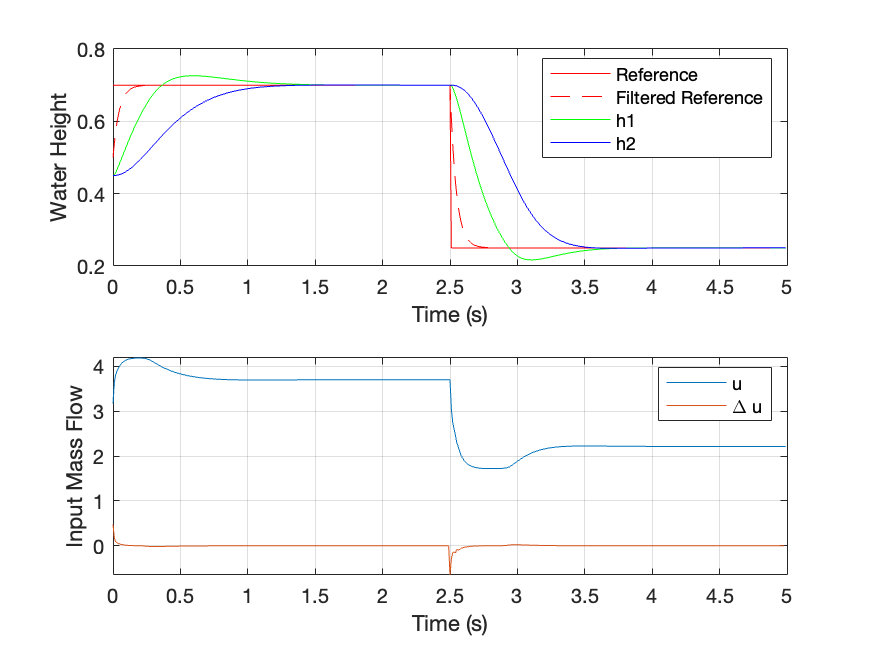

%% Plots

ax1 = subplot(2,1,1);
plot(time,r,'r',time,rf_dat,'--r',time,h1_dat,'g',time,h2_dat,'b')
grid on
legend('Reference','Filtered Reference','h1','h2')
xlabel('Time (s)')
ylabel('Water Height')

ax2 = subplot(2,1,2);
plot(time,u_dat,time(1:end-1),diff(u_dat))
grid on
legend('u','\Delta u')
xlabel('Time (s)')
ylabel('Input Mass Flow')

linkaxes([ax1,ax2 ],'x')

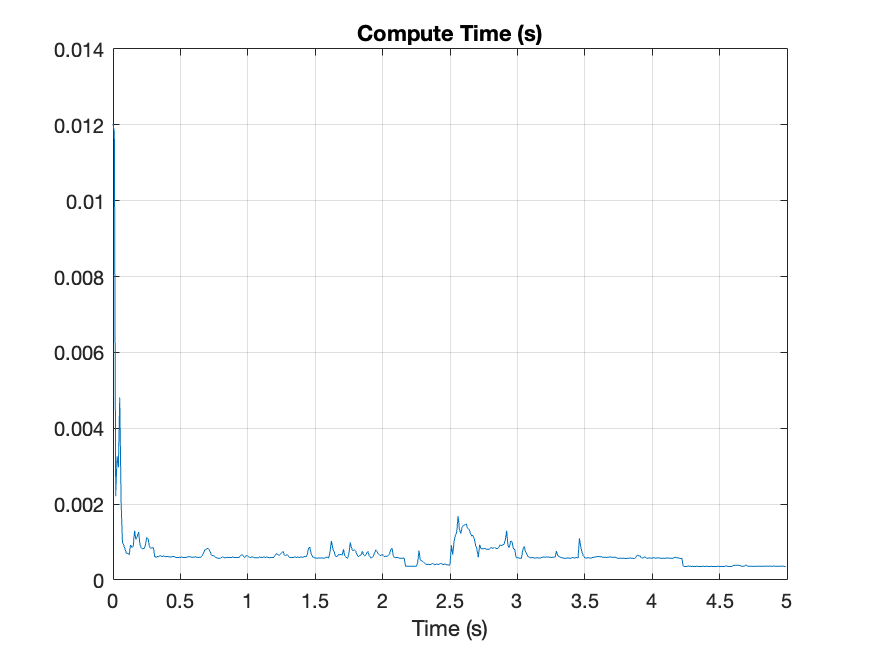


figure
plot(time,t_dat)
title('Compute Time (s)')
xlabel('Time (s)')
grid on

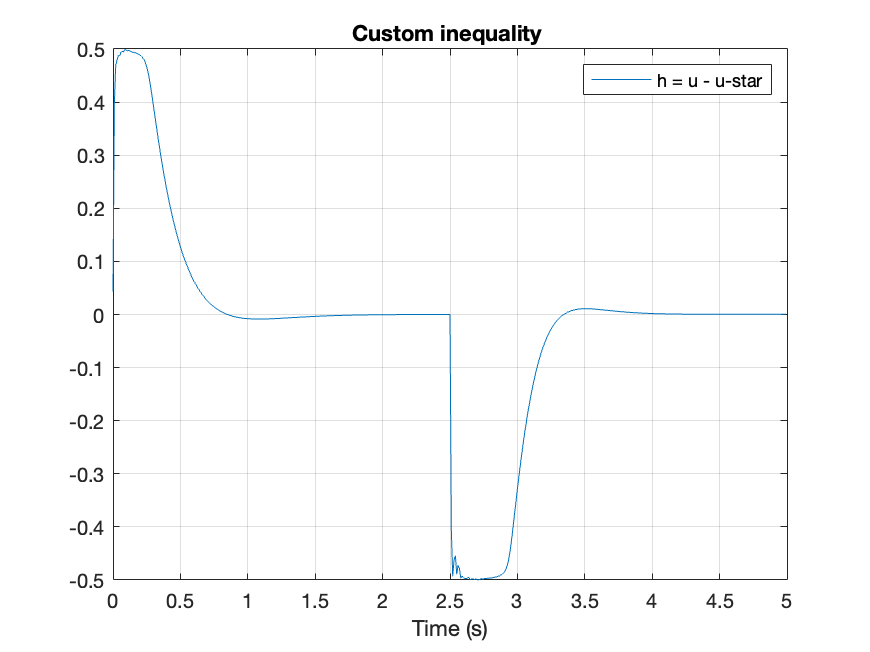


figure
plot(time, u_dat - u_star_dat)
title('Custom inequality ')
xlabel('Time (s)')
grid on
legend('h = u - u-star')